# SEGMENTACIÓN

% figure; 
T=readtable('T_revisada_BuenaCalidad.csv')

T = 149×2 table
          image           glaucoma
    __________________    ________

    {'image_0009.jpg'}       0    
    {'image_0032.jpg'}       1    
    {'image_0048.jpg'}       0    
    {'image_0069.jpg'}       0    
    {'image_0078.jpg'}       0    
    {'image_0086.jpg'}       1    
    {'image_0094.jpg'}       0    
    {'image_0098.jpg'}       0    
    {'image_0128.jpg'}       1    
    {'image_0142.jpg'}       0    
    {'image_0175.jpg'}       0    
    {'image_0176.jpg'}       0    
    {'image_0206.jpg'}       0    
    {'image_0207.jpg'}       1    
    {'image_0208.jpg'}       0    
    {'image_0235.jpg'}       0    


directorio_origen = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\BuenaCalidad_BASE';
% Carpeta de destino para guardar las imágenes de buena calidad
carpeta_destino = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\ROI';
resultados = table('Size', [height(T) 2], 'VariableTypes', {'string', 'double'}, 'VariableNames', {'image', 'glaucoma'});
for i = 1:height(T)
    nombre_imagen = T.image{i};
    I_origen = imread(T.image{i});

    I_gray=rgb2gray(I_origen);
    I_thresholded=imbinarize(I_gray,0.1);
    % imshow(I_thresholded)
    
    se = strel('disk', 40);
    I_sinpunto=imopen(I_thresholded,se);
    % imshow(I_sinpunto)
    I_double=im2double(I_origen);
    
    I_double(:,:,1)=I_double(:,:,1).*I_sinpunto;
    I_double(:,:,2)=I_double(:,:,2).*I_sinpunto;
    I_double(:,:,3)=I_double(:,:,3).*I_sinpunto;
    % imshow(I_double)
    
    se=strel('disk', 90);
    I_encogido=imerode(I_sinpunto,se);
    % imshow(I_encogido)
    I_double(:,:,1)=I_double(:,:,1).*I_encogido;
    I_double(:,:,2)=I_double(:,:,2).*I_encogido;
    I_double(:,:,3)=I_double(:,:,3).*I_encogido;

    I_gray_2=rgb2gray(I_double);

    I_iluminadomejor=adapthisteq(I_gray_2);

    [max_intensity, max_index] = max(I_iluminadomejor(:));
    [max_row, max_col] = ind2sub(size(I_iluminadomejor), max_index);
    square_size = 1300;
    
    % Calcular las coordenadas del cuadrado de recorte
    row_start = max(1, max_row - square_size/2);
    row_end = min(size(I_iluminadomejor, 1), max_row + square_size/2 - 1);
    col_start = max(1, max_col - square_size/2);
    col_end = min(size(I_iluminadomejor, 2), max_col + square_size/2 - 1);
    
    % Recortar la imagen
    cropped_image = I_origen(row_start:row_end, col_start:col_end, :);
    figure; 
    
    % subplot(1,2,1)
    % imshow(cropped_image);
    
    % Guardar la imagen recortada en la carpeta de destino
    nombre_completo = fullfile(carpeta_destino, nombre_imagen);
    imwrite(cropped_image, nombre_completo);

    resultados.image(i) = nombre_imagen;
    resultados.glaucoma(i) = T.glaucoma(i);
end 
ROI_CalidadRevisada = 'ROI_CalidadRevisada.csv';
writetable(resultados, fullfile(carpeta_destino, ROI_CalidadRevisada));

%SEGMENTACIÓN DE LOS ROI
close all; 
T_ROI=readtable('ROI\ROI_CalidadRevisada.csv')

T_ROI = 149×2 table
          image           glaucoma
    __________________    ________

    {'image_0009.jpg'}       0    
    {'image_0032.jpg'}       1    
    {'image_0048.jpg'}       0    
    {'image_0069.jpg'}       0    
    {'image_0078.jpg'}       0    
    {'image_0086.jpg'}       1    
    {'image_0094.jpg'}       0    
    {'image_0098.jpg'}       0    
    {'image_0128.jpg'}       1    
    {'image_0142.jpg'}       0    
    {'image_0175.jpg'}       0    
    {'image_0176.jpg'}       0    
    {'image_0206.jpg'}       0    
    {'image_0207.jpg'}       1    
    {'image_0208.jpg'}       0    
    {'image_0235.jpg'}       0    


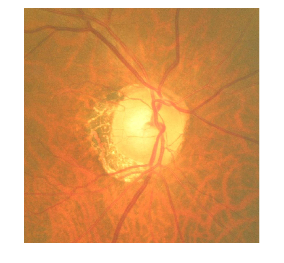


directorio_origen = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\ROI';
% Carpeta de destino para guardar las imágenes de buena calidad
carpeta_destino = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\ROI_Segmetado';
% Inicializar vectores para almacenar las entropías
entropias_rojo = zeros(height(T_ROI), 1);
entropias_verde = zeros(height(T_ROI), 1);
entropias_azul = zeros(height(T_ROI), 1);
% 
% for i = 1:height(T_ROI)
%     nombre_imagen = T_ROI.image{i}; 

    ROI_origen= imread(T_ROI.image{35});
    imshow(ROI_origen)

    canal_rojo= ROI_origen(:,:,1);
    canal_verde= ROI_origen(:,:,2);
    canal_azul= ROI_origen(:,:,3);

    % subplot(4, 3, 1);  imshow(canal_rojo); title('ROI_Canal Rojo');
    % subplot(4, 3, 2);  imshow(canal_verde); title('ROI_Canal Verde');
    % subplot(4, 3, 3);  imshow(canal_azul); title('ROI_Canal Azul');

    entropias_rojo(i) = entropy(canal_rojo);
    entropias_verde(i) = entropy(canal_verde);
    entropias_azul(i) = entropy(canal_azul);
    
    fprintf('entropia_rojo %d: %f\n', i, entropias_rojo(i));

entropia_rojo 149: 6.614750


    fprintf('entropia_verde %d: %f\n', i, entropias_verde(i));

entropia_verde 149: 5.847059


    fprintf('entropia_azul %d: %f\n', i, entropias_azul(i));

entropia_azul 149: 5.132927


    
    % se = strel('disk', 300); 
    % background_rojo = imopen(canal_rojo, se);
    % background_verde = imopen(canal_verde, se);
    % background_azul = imopen(canal_azul, se);
    % 
    % corrected_image_rojo = imsubtract(canal_rojo, background_rojo);
    % corrected_image_verde = imsubtract(canal_verde, background_verde);
    % corrected_image_azul = imsubtract(canal_azul, background_azul);
    % fixed_dc_level = 100; 
    % I_iluminado_rojo = corrected_image_rojo + fixed_dc_level;
    % I_iluminado_verde = corrected_image_verde + fixed_dc_level;
    % I_iluminado_azul= corrected_image_azul + fixed_dc_level;
    % 
    % subplot(4, 3, 4); title('ROI_Canal Rojo'); imshow(I_iluminado_rojo)
    % subplot(4, 3, 5); title('ROI_Canal Verde'); imshow(I_iluminado_verde)
    % subplot(4, 3, 6); title('ROI_Canal Azul'); imshow(I_iluminado_azul)
    
    se = strel('disk', 20);
    I_vessels_rojo = imclose(canal_rojo, se);
    I_vessels_verde = imclose(canal_verde, se);
    I_vessels_azul = imclose(canal_azul, se);

    I_sinvenas_rojo=imadjust(I_vessels_rojo); 
    I_sinvenas_verde=imadjust(I_vessels_verde);
    I_sinvenas_azul=imadjust(I_vessels_azul);
    % 
    subplot(4, 3, 4);  imshow(I_sinvenas_rojo); 
    subplot(4, 3, 5);  imshow(I_sinvenas_verde); 
    subplot(4, 3, 6);  imshow(I_sinvenas_azul); 

    sorted_values_rojo = sort(I_sinvenas_rojo(:), 'descend');
    sorted_values_verde = sort(I_sinvenas_verde(:), 'descend');
    sorted_values_azul = sort(I_sinvenas_azul(:), 'descend');

    % Aplicar umbral para seleccionar el % de los píxeles de máxima calidad
    threshold_index_disc_rojo = round(0.04 * numel(sorted_values_rojo));
    threshold_value_disc_rojo = sorted_values_rojo(threshold_index_disc_rojo);
    I_thresholded_disc_rojo_inicial = I_sinvenas_rojo >= threshold_value_disc_rojo;

    threshold_index_disc_verde = round(0.08* numel(sorted_values_verde));
    threshold_value_disc_verde = sorted_values_verde(threshold_index_disc_verde);
    I_thresholded_disc_verde_inicial = I_sinvenas_verde >= threshold_value_disc_verde;

    threshold_index_disc_azul = round(0.03 * numel(sorted_values_azul));
    threshold_value_disc_azul = sorted_values_azul(threshold_index_disc_azul);
    I_thresholded_disc_azul_inicial = I_sinvenas_azul >= threshold_value_disc_azul;

    if entropias_rojo(i)>=6 
     
        I_thresholded_disc_rojo_final = I_sinvenas_rojo >= threshold_value_disc_rojo;
        Disco_segmentado_rojo=  I_thresholded_disc_rojo_final

    else
        I_thresholded_disc_rojo_final=ones(size(canal_rojo));
        Disco_segmentado_rojo=0;
    end 

Disco_segmentado_rojo = 1300×1300 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

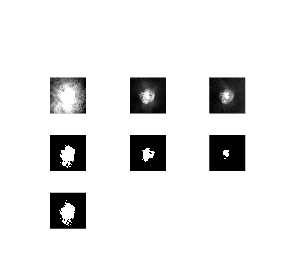


    if entropias_verde (i)>=4.4 && entropias_verde (i)<6.2&& entropias_verde (i)<entropias_azul(i) && entropias_rojo(i)<6
   
        I_thresholded_disc_verde_final = I_sinvenas_verde >= threshold_value_disc_verde;
            
    else
   
        I_thresholded_disc_verde_final=ones(size(canal_verde));
        
    end 

    if entropias_azul (i)>=4.3 && entropias_rojo(i)<6
    
       I_thresholded_disc_azul_final = I_sinvenas_azul >= threshold_value_disc_azul;
       
    
    else 
       
        I_thresholded_disc_azul_final= ones(size(canal_azul));
        
    end 

if Disco_segmentado_rojo
    Disco_segmentado_final=Disco_segmentado_rojo;
else 
 Disco_segmentado_final=  I_thresholded_disc_rojo_final & I_thresholded_disc_verde_final & I_thresholded_disc_azul_final;
end 
   
    
    subplot(4, 3, 7);  imshow(I_thresholded_disc_rojo_inicial)
    subplot(4, 3, 8);  imshow(I_thresholded_disc_verde_inicial)
    subplot(4, 3, 9);  imshow(I_thresholded_disc_azul_inicial)

    subplot(4, 3, 10);  imshow(I_thresholded_disc_rojo_final)
    subplot(4, 3, 11);  imshow(I_thresholded_disc_verde_final)
    subplot(4, 3, 12);  imshow(I_thresholded_disc_azul_final)

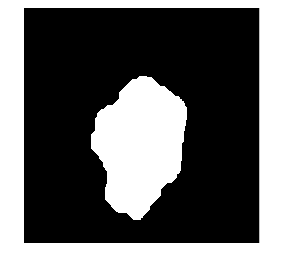

Disco_quitando_alrededor = 1300×1300 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

Disco_volver = 1300×1300 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 


    figure; 
if Disco_segmentado_rojo
    Disco_segmentado_entero=Disco_segmentado_final;
else 
se = strel('disk', 20);
    Disco_quitando_alrededor=imerode(Disco_segmentado_final,se)
    imshow(Disco_quitando_alrededor);
    Disco_volver=imdilate(Disco_quitando_alrededor,se)
    imshow(Disco_volver);
    se = strel('disk', 70);
    Disco_segmentado_relleno=imclose(Disco_volver,se);
    imshow(Disco_segmentado_relleno);
    se = strel('disk', 50);
    Disco_segmentado_entero=imopen(Disco_segmentado_relleno,se);
    imshow(Disco_segmentado_entero);
end 

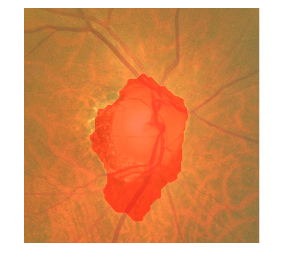

    
    % se = strel('disk', 40);
    % Disco_segmentado_cerrado=imclose(Disco_segmentado_relleno,se);

    figure; 
    title('ROI Combinada (AND)');
    imshow(ROI_origen);
    hold on;
    
    % Encontrar contornos de la imagen combinada
    [B, L] = bwboundaries(Disco_segmentado_relleno, 'noholes');
    
    % Dibujar cada contorno encontrado
    for k = 1:length(B)
        boundary = B{k};
        fill(boundary(:,2), boundary(:,1), 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    end
    hold off;

% 
%     nombre_completo = fullfile(carpeta_destino, nombre_imagen);
%     imwrite(Disco_segmentado_relleno, nombre_completo);
% end
